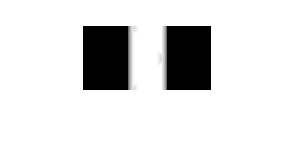

clear all
load('sino-phantom-64x128.mat');

imshow(g0)

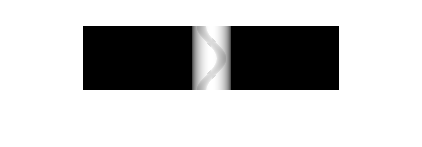

[height,width]=size(g0);

%we add the 0padding
mat=zeros(height,2*width);
mat(:,width/2+1:width+width/2)=g0;

%display the image with 0padding
imshow(mat,[])

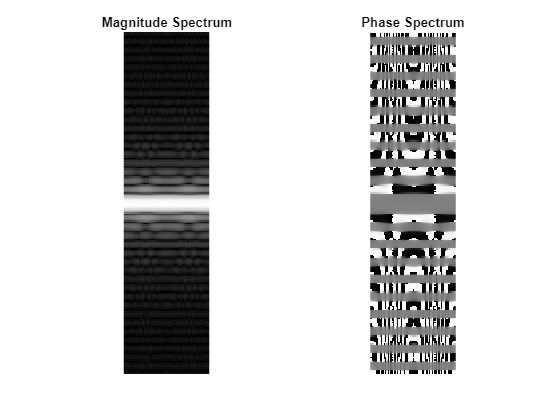


%fourier tranformation
fourier_transform = fft(fftshift(mat'));
shifted_transform = fftshift(fourier_transform);

%find magnitude and phase
magnitude_spectrum = abs(shifted_transform);
phase_spectrum = angle(shifted_transform);

%we construct the filter
f=[-pi:2*pi/256:pi]';
filtername='RamLak';
filter=Filtering(filtername,f(2:width*2+1));

%display magnitude and phase
figure;
subplot(1, 2, 1);
imshow(log(1 + magnitude_spectrum), []);
title('Magnitude Spectrum');
subplot(1, 2, 2);
imshow(phase_spectrum, []);
title('Phase Spectrum');

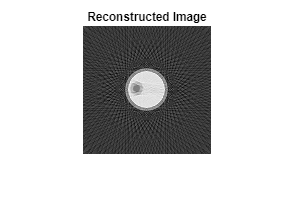



%apply the filter
size_2=size(fourier_transform);
for i=1:size_2(2)
    back_proj(:,i)=shifted_transform(:,i).*filter;   
end


fourier_transform=back_proj;
shifted_transform = fftshift(fourier_transform);

%inverse fourier transform
inverse_transform = ifft(shifted_transform);
shifted_transform = fftshift(inverse_transform);
shifted_transform=shifted_transform';

%theta is a vector 2pi  length with step of 2pi/number of columns
theta=0:2*pi/height:2*pi;
theta(1)=[];
final_image=zeros(width,width);

%convert the polar coordinates to cartesian doing the integral
[x,y]=meshgrid(-(width/2-1):width/2);
for i=1:length(theta)

    %here we do the integral
    r=floor(x.*cos(theta(i))+y.*sin(theta(i))+width);
    proj=shifted_transform(i,:);
    final_image=final_image+proj(r);
end

%display finale image
figure;
imshow(real(final_image), []);
title('Reconstructed Image');

function filter= Filtering(filtname,f)
filter = 0.5*((2*pi)^(-1.5))*abs(f);
    if filtname == 'RamLak'      
    elseif filtname == 'Cosine'    
        filter = filter.*cos((abs(f)*pi)/(2*pi)); 
    elseif filtname == 'SheLog'    
        filter = filter.*(sin((abs(f)*pi)/(2*pi))./((abs(f)*pi)/(2*pi)));     
        filter(f==0) = 0; 
    end
end